# Mixed sensitivity design

Goal of the $H_{\;\infty }$ controller synthesis is to give the sensitivity $\left(S\right)$ and the complementary sensitivity function $\left(T\right)$ a desired shape. These two functions affect many of the feedback properties and by bounding (limiting) them with weighting functions we can for example set a desired trade off between robustness and pefrormance. 

- Bound of $H_{\;\infty }$ norm on *S* affects performance

- Bound of $H_{\;\infty }$ norm on *T* affects robustness and sensitivity to noise

- Full mixed sensitivity design also binds $H_{\;\infty }$ norm of $\textrm{KS}$ function to penalize large inputs

These requirements are often combined into a stacked $H_{\;\infty }$ problem:


$$$\min_K\left\|\matrix{W_PS \cr W_TT \cr W_uKS}\right\|_\infty$$$


If we have denote the optimization output $$z=\left(\matrix{W_PS \cr W_TT \cr W_uKS}\right)w$$, then the objective is to minimize the $H_{\;\infty }$ norm from exogenout input *w* to the optimized output $z$.

## Shaping of S and T

For the purpose of this exercise the objective will reduced to:


$$$\min_K\left\|\matrix{W_PS \cr W_TT}\right\|_\infty$$$


(no penalization of large inputs)

By introducing $u=\textrm{Ky}$ the resulting objective can be also visualized by the following block diagram:

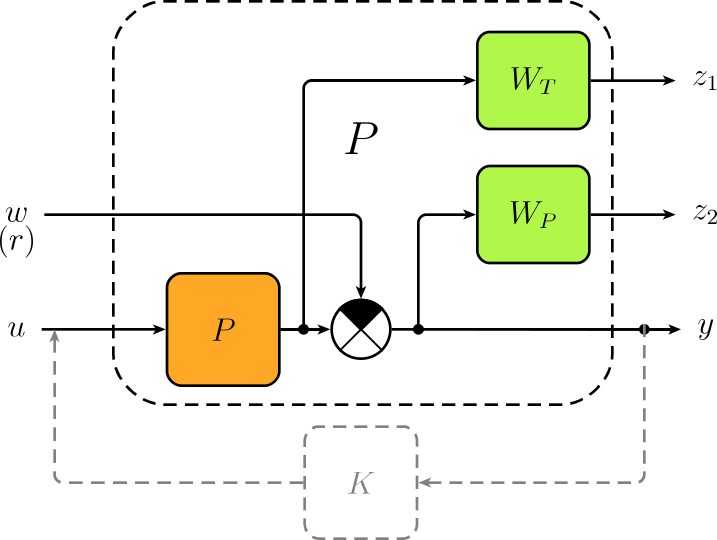

Which is just re-arranged one degree of freedom control diagram:

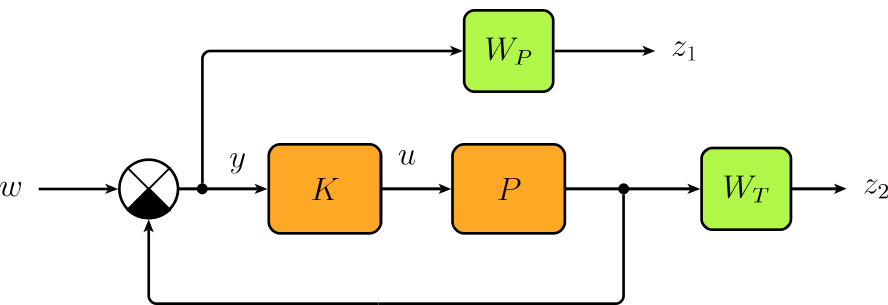

Both S and T are bound (limited) from above by inverse of its wighting function so that:

$$\left|\matrix{S \cr T}\right|<\left|\matrix{1/W_P \cr 1/W_T}\right|$$        S+T = 1 vzdy plati => upravime-li S tim padem upravime i T. Vzdy totiz plata dana rovnice

This can be visualized for the sensitivity function in frequency domain as:

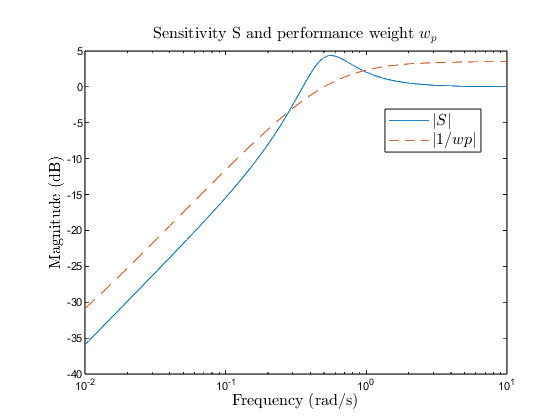

$H_{\;\infty }$ optimization criteria $$\min_K\left\|\matrix{W_PS \cr W_TT}\right\|_\infty$$ then minimazes norm of weighted function as visualized on the following frequency response:

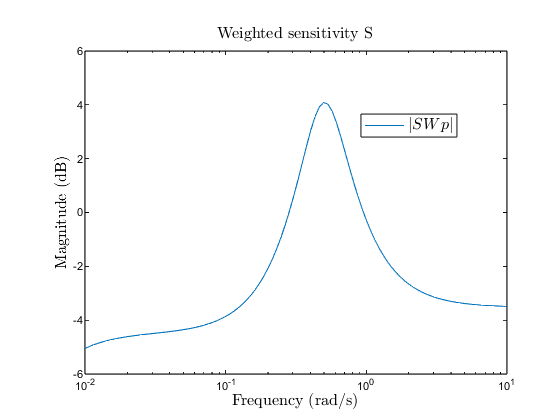

Where the highest peak has a value of $$\|SW_p\|_\infty$$ (approx 4dB).

For most of the controlled systems following weight is sufficient for shaping the sensitivity function:


$$$w_p=\frac{s/M+\omega_B}{s+\omega_BA}$$$


Inverse of this weight ($1/\textrm{wp}$) has gain of $A\le 1$at low frequencies and $M\ge 1$at high frequencies with 0dB crossing at $\omega_B$.

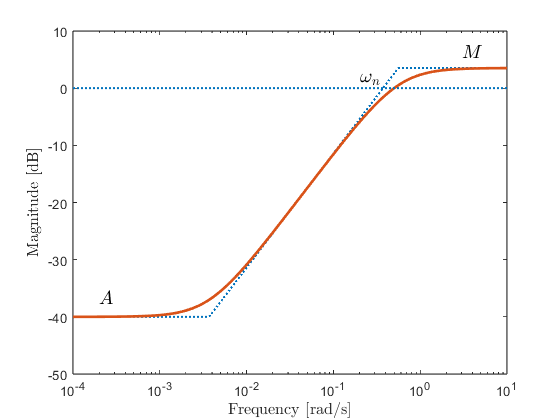

# Model of the Mass/damper/spring system

Model of the MSD is taken from the exercise 7 - uncertainties. See the exercise 7 for details about this system.

## Uncertain state-space model of MSD

mnom = 3;
cnom = 1;
knom = 2;
pm = 0.4; %4
pc = 0.4; %2
pk = 0.3; %3

m = ureal('mass',mnom,'Percentage',pm);
c = ureal('friction',cnom,'Percentage',pc);
k = ureal('elasticity',knom,'Percentage',pk);

A = [  0     1
     -k/m  -c/m];
B = [0;
      1/m];
C = [1 0];

D = [0];

G = uss(A,B,C,D);

G.StateName = {'body travel xb [m]';'body velocity [m/s]'}; % state names
G.InputName = 'u';                                          % for "connect" func
G.OutputName = 'y';                                         % for "connect" func

## Definition of weights

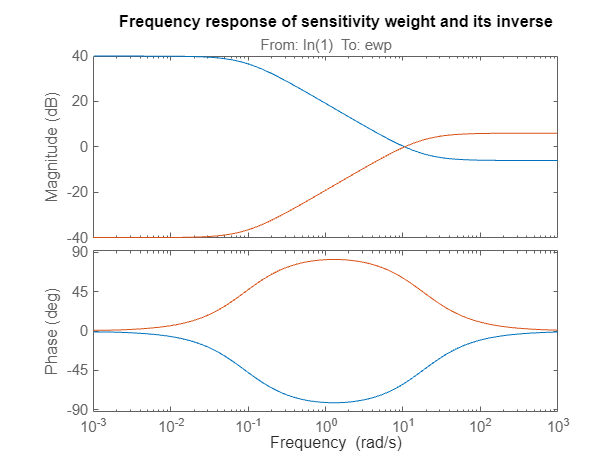

A = 1/100;          % 1% error / ustalena reg. odchylka 1%
M = 2;              % 0.5 stability margin / zasoba stab. v modulu 0.5
%wb = ;           % cross freq. / frekvence rezu
wb =10.5; % FILL IN - set to correct value
% Vahovaci funkce (vaha) citlivostni funkce
% Sensitivity function weight - pick one approach

%s = tf('s');
%Wp = ;
% OR
%Wp = ltisys('tf',,); 
% OR
Wp = makeweight(1/A,wb, 1/M);   % FILL IN / Choose

% Name IO - for "connect" function
Wp.InputName = 'e';
Wp.OutputName = 'ewp';

figure
bode(Wp,1/Wp)
title('Frequency response of sensitivity weight and its inverse')

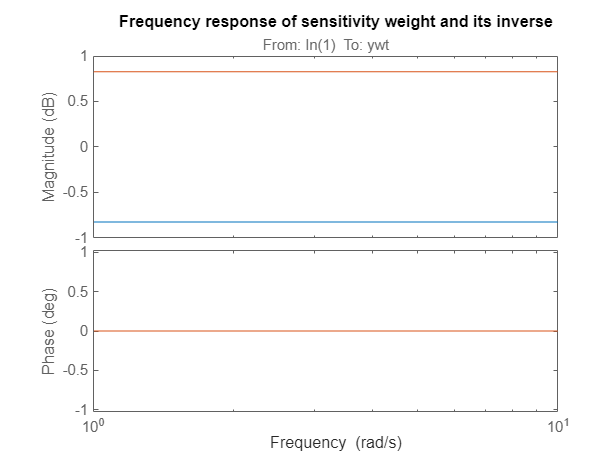


% Complementary sensitivity weight
Wt = ss(tf(1,1.1));       % 10% prekmit vystupni veliciny / 10% overshot % FILL IN
Wt.InputName = 'y';
Wt.OutputName = 'ywt';

figure
bode(Wt,1/Wt)
title('Frequency response of sensitivity weight and its inverse')

## Definition of general feedback diagram for controller synthesis - 2 inputs, 3 outputs

% sumator ve state tttspace
% subtraction block in state space
Sum = sumblk('e = r - y'); % FILL IN                       

% pouziti connectu pro vytvoreni regulacniho obvodu rozsireneho o vahy
% use connect function to realize feedback augmented with weigting functions
system = connect(G,Wt,Wp,Sum,{'r';'u'},{'ewp';'ywt';'e'}); % FILL IN
% ted rekneme hinfsynu ktere vstupy ovlivnuje a ktere vystupy jdou do regulatoru
% it is necessary to specify number of control inputs (u) and measurement
% outputs (y)
nmeas = 1;  % pocet merenich velicin (reg. odchylka) / n. of measures
ncon = 1;   % pocet akcnich velicin / n. of controls

## Controller synthesis

% cilova hodnota gamma (v tomto pripade odchylka od vahovaci fce)
% target gamma
gmin = 1.0;     
% nejhorsi mozna gamma
% worst case gamma
gmax = 2;    
% tolerance minimalizacniho kriteria
% optimization tolerance
tol = 0.001;                                    
[K,CL,gam] = hinfsyn(system,nmeas,ncon,'GMIN',gmin,'GMAX',gmax,'TOLGAM',tol,'DISPLAY','on','METHOD','lmi');


 Minimization of gamma:

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3                   5.115534
     4                   4.105183
     5                   3.528519
     6                   2.755166
     7                   2.257130
     8                   2.113348
     9                   2.113348
    10                   1.478852
    11                   1.391795
    12                   1.309709
    13                   1.233318
    14                   1.233318
    15                   1.016171
    16                   1.016171
    17                   1.016171
    18                   0.977720

 Result:  reached the target for the objective value
          best objective value:     0.977720
          f-radius saturation:  2.591% of R =  1.00e+08 
 
 Optimal Hinf performance:  9.280e-01 



disp(gam)

    0.9265



% definice v/v pro connect
% i/o def. for connect
K.InputName = 'e';  
K.OutputName = 'u';

Lets check the required sampling time so that we know if its possible to realize the controller inside DSP. For this purpose we can use the spectral radius $\rho \;$which is calculated as the largest absolute eigenvalue of the controller. Sampling time needs to be double the $\rho$ in order to satisfy the sampling theorem.

SpectralRadius = max(abs(eig(K.a)));
disp(join(["Sampling time =",string(SpectralRadius),"x2"]))

Sampling time = 239.96 x2


## Defining feedback system again (this time without weights) for simulation

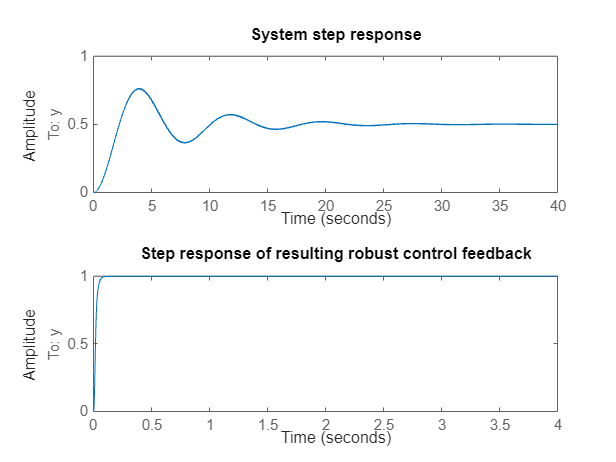

simsys = connect(G,K,Sum,{'r'},{'y'}); % FILL IN

figure
t = 0:0.01:40;
u = 0*t+1;
subplot(2,1,1)
lsim(G,u',t')
title('System step response')
subplot(2,1,2)
lsim(simsys,u',t./10')
title('Step response of resulting robust control feedback')

## Verification of frequency response for S and T

We need to verify that the criteria specified by weight functions were met:


$$$\left|\matrix{S \cr T}\right|<\left|\matrix{1/W_P \cr 1/W_T}\right|$$$


E.g. apmlitudes of S&T frequency responses are under their respective bounds (inverses of weights).

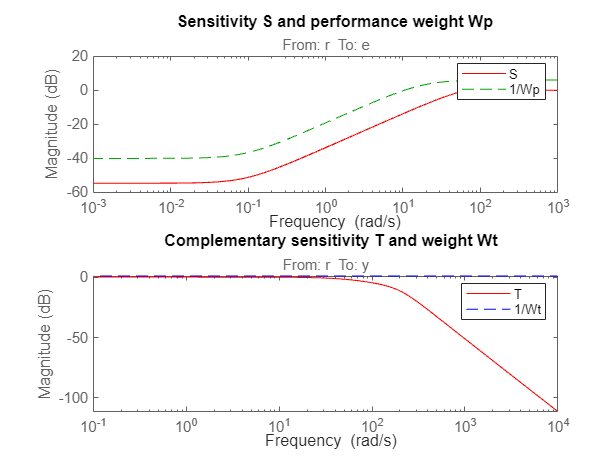

versys = connect(G,Sum,K,{'r'},{'e';'y'});
figure
subplot(2,1,1)
bodemag(versys(1),'r');
hold on
bodemag(1/Wp,'--g')
legend('S','1/Wp')
title('Sensitivity S and performance weight Wp')
subplot(2,1,2)
bodemag(versys(2),'r');
hold on
bodemag(1/Wt,'--b')
legend('T','1/Wt')
title('Complementary sensitivity T and weight Wt')

We can also directly visualize the achived values of $\gamma \;$.

If $$\left\|\matrix{W_PS \cr W_TT}\right\|_\infty<1$$ then the bounds were satisfied and optimization criterie were met.

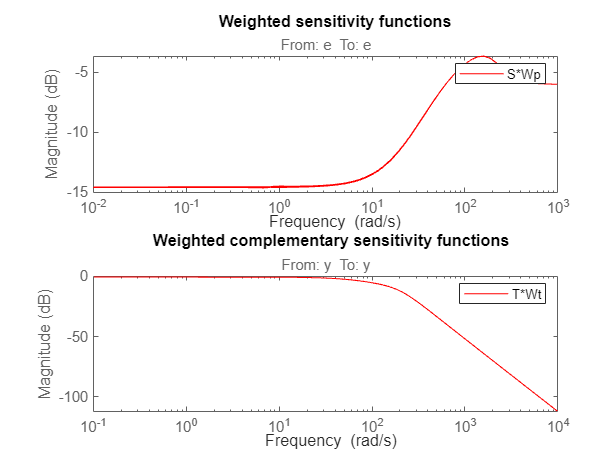

figure
subplot(2,1,1)
bodemag(versys(1)*Wp,'r');
legend('S*Wp')
title('Weighted sensitivity functions')

subplot(2,1,2)
bodemag(versys(2)*Wt,'r');
legend('T*Wt')
title('Weighted complementary sensitivity functions')